# Exam February 5, 2018

## Exercise 1

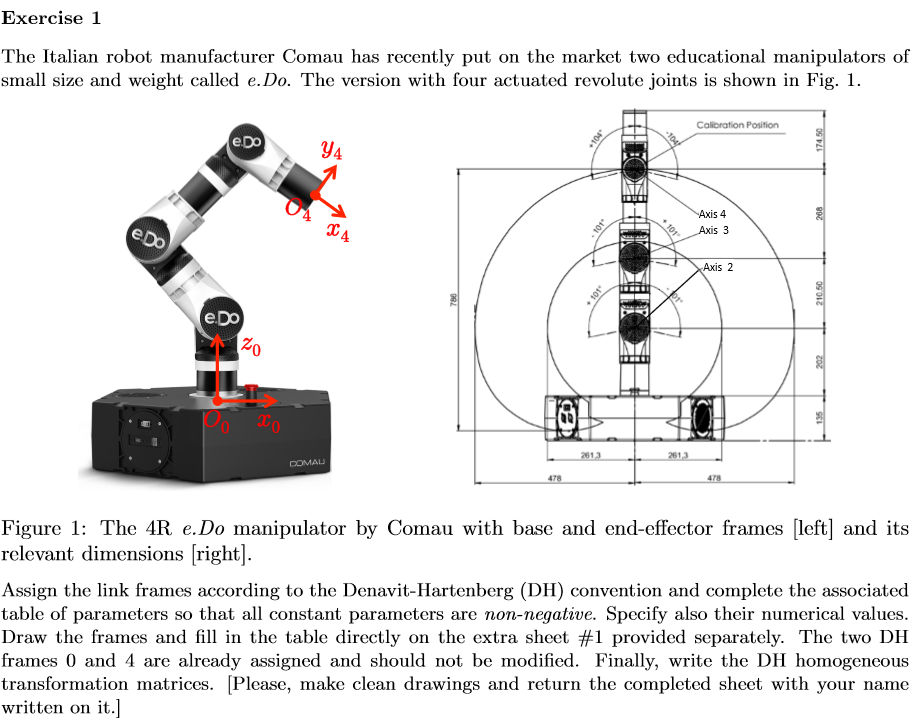

close all
clear all
clc

NJoints=4

NJoints =           4.00



q = sym('q',[1 4])

$$q = \left(\begin{array}{cccc} q_{1} & q_{2} & q_{3} & q_{4} \end{array}\right)$$

d = sym('d',[1 4])

$$d = \left(\begin{array}{cccc} d_{1} & d_{2} & d_{3} & d_{4} \end{array}\right)$$

dh = [pi/2 0 202 q(1);
        0   210.5 0  q(2);
        0   268  0  q(3);
        0   174.5 0  q(4)]

$$dh = \left(\begin{array}{cccc} \frac{\pi }{2} & 0 & 202 & q_{1}\\ 0 & \frac{421}{2} & 0 & q_{2}\\ 0 & 268 & 0 & q_{3}\\ 0 & \frac{349}{2} & 0 & q_{4} \end{array}\right)$$

dht = getDHforTB(dh,'alpha')

n =           4.00


dht =              0        202.00             0          1.57
             0             0        210.50             0
             0             0        268.00             0
             0             0        174.50             0


comau = SerialLink(dht)

 
comau = 
 
noname:: 4 axis, RRRR, stdDH, slowRNE                            
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|        202|          0|     1.5708|          0|
|  2|         q2|          0|      210.5|          0|          0|
|  3|         q3|          0|        268|          0|          0|
|  4|         q4|          0|      174.5|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


olddigits=digits(4)

olddigits =          32.00


for i_=1:NJoints
   vpa(comau.links(i_).A(q(i_)))
end

$$\left(\begin{array}{cccc} \cos\left(q_{1}\right) & -6.123e-17\,\sin\left(q_{1}\right) & \sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & 6.123e-17\,\cos\left(q_{1}\right) & -1.0\,\cos\left(q_{1}\right) & 0\\ 0 & 1.0 & 6.123e-17 & 202.0\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

$$\left(\begin{array}{cccc} \cos\left(q_{2}\right) & -1.0\,\sin\left(q_{2}\right) & 0 & 210.5\,\cos\left(q_{2}\right)\\ \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 0 & 210.5\,\sin\left(q_{2}\right)\\ 0 & 0 & 1.0 & 0\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

$$\left(\begin{array}{cccc} \cos\left(q_{3}\right) & -1.0\,\sin\left(q_{3}\right) & 0 & 268.0\,\cos\left(q_{3}\right)\\ \sin\left(q_{3}\right) & \cos\left(q_{3}\right) & 0 & 268.0\,\sin\left(q_{3}\right)\\ 0 & 0 & 1.0 & 0\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

$$\left(\begin{array}{cccc} \cos\left(q_{4}\right) & -1.0\,\sin\left(q_{4}\right) & 0 & 174.5\,\cos\left(q_{4}\right)\\ \sin\left(q_{4}\right) & \cos\left(q_{4}\right) & 0 & 174.5\,\sin\left(q_{4}\right)\\ 0 & 0 & 1.0 & 0\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

digits(olddigits)
comau.teach([0 0 0 0])

## Exercise 4

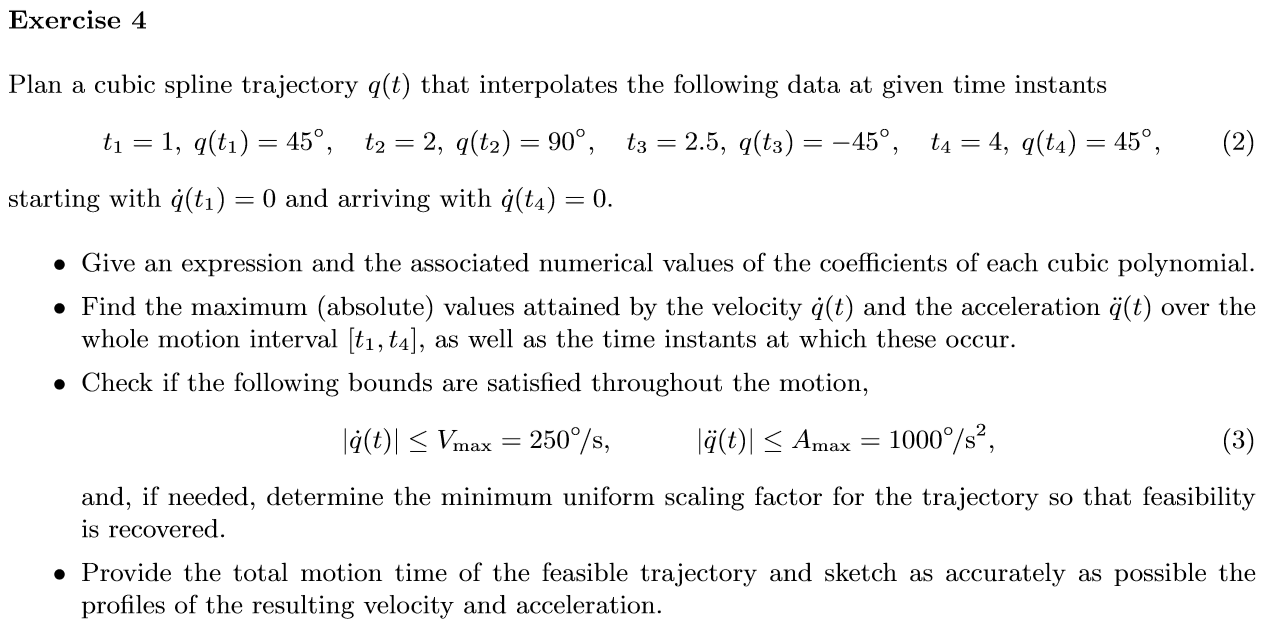

The pieces of the function must be continuous in velocity, and start and finish in zero speed (Rest-to-Rest). Those are the conditions listed below.

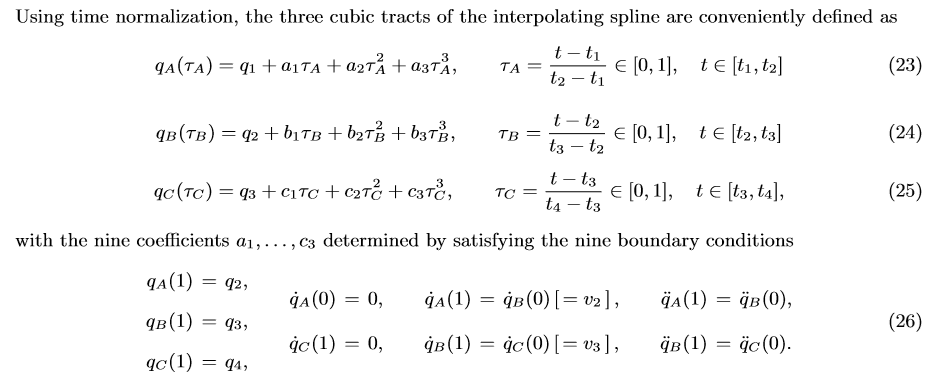

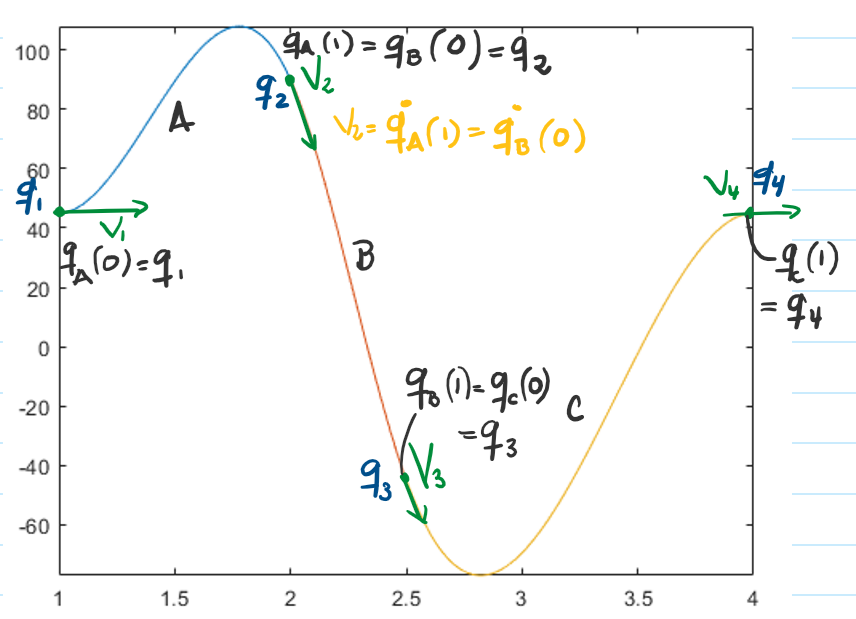

q = sym('q',[1,4]);

syms t t1 t2 v2 v3 t3 t4

### Part A

a = sym('a',[1 3]);
tao = (t-t1)/(t2-t1)

$$tao = -\frac{t-t_{1}}{t_{1}-t_{2}}$$

qa = q(1) + a(1)*tao + a(2)*tao^2 + a(3)*tao^3 %tao must be defined as a function of t

$$qa = q_{1}-\frac{a_{1}\,\left(t-t_{1}\right)}{t_{1}-t_{2}}+\frac{a_{2}\,{\left(t-t_{1}\right)}^{2}}{{\left(t_{1}-t_{2}\right)}^{2}}-\frac{a_{3}\,{\left(t-t_{1}\right)}^{3}}{{\left(t_{1}-t_{2}\right)}^{3}}$$

wa = diff(qa,t)

$$wa = \frac{a_{2}\,\left(2\,t-2\,t_{1}\right)}{{\left(t_{1}-t_{2}\right)}^{2}}-\frac{a_{1}}{t_{1}-t_{2}}-\frac{3\,a_{3}\,{\left(t-t_{1}\right)}^{2}}{{\left(t_{1}-t_{2}\right)}^{3}}$$

% Forming the equation system for part A

eqA(1) = subs(qa,t,t2) == q(2);
eqA(2) = simplify(subs(wa,t,t1)) == 0; % t = t1 is tao = 0
eqA(3) = simplify(subs(wa,t,t2)) == v2; % t = t2 is tao = 1
eqA.'

$$ans = \left(\begin{array}{c} a_{1}+a_{2}+a_{3}+q_{1}=q_{2}\\ -\frac{a_{1}}{t_{1}-t_{2}}=0\\ -\frac{a_{1}+2\,a_{2}+3\,a_{3}}{t_{1}-t_{2}}=v_{2} \end{array}\right)$$

[a1 a2 a3] = solve(eqA.',a)

$$a1 = 0$$

$$a2 = 3\,q_{2}-3\,q_{1}+t_{1}\,v_{2}-t_{2}\,v_{2}$$

$$a3 = 2\,q_{1}-2\,q_{2}-t_{1}\,v_{2}+t_{2}\,v_{2}$$

### Part B

taob = (t-t2)/(t3-t2)

$$taob = -\frac{t-t_{2}}{t_{2}-t_{3}}$$

b = sym('b',[1 3]);

qb = q(2) + b(1)*taob + b(2)*taob^2 + b(3)*taob^3 %tao must be defined as a function of t

$$qb = q_{2}-\frac{b_{1}\,\left(t-t_{2}\right)}{t_{2}-t_{3}}+\frac{b_{2}\,{\left(t-t_{2}\right)}^{2}}{{\left(t_{2}-t_{3}\right)}^{2}}-\frac{b_{3}\,{\left(t-t_{2}\right)}^{3}}{{\left(t_{2}-t_{3}\right)}^{3}}$$

wb = diff(qb,t)

$$wb = \frac{b_{2}\,\left(2\,t-2\,t_{2}\right)}{{\left(t_{2}-t_{3}\right)}^{2}}-\frac{b_{1}}{t_{2}-t_{3}}-\frac{3\,b_{3}\,{\left(t-t_{2}\right)}^{2}}{{\left(t_{2}-t_{3}\right)}^{3}}$$

 
% Forming the equation system for part B

eqB(1) = subs(qb,t,t3) == q(3);
eqB(2) = simplify(subs(wb,t,t2)) == v2; % t = t1 is tao = 0
eqB(3) = simplify(subs(wb,t,t3)) == v3; % t = t2 is tao = 1
eqB.'

$$ans = \left(\begin{array}{c} b_{1}+b_{2}+b_{3}+q_{2}=q_{3}\\ -\frac{b_{1}}{t_{2}-t_{3}}=v_{2}\\ -\frac{b_{1}+2\,b_{2}+3\,b_{3}}{t_{2}-t_{3}}=v_{3} \end{array}\right)$$

[b1 b2 b3] = solve(eqB.',b) 

$$b1 = t_{3}\,v_{2}-t_{2}\,v_{2}$$

$$b2 = 3\,q_{3}-3\,q_{2}+2\,t_{2}\,v_{2}+t_{2}\,v_{3}-2\,t_{3}\,v_{2}-t_{3}\,v_{3}$$

$$b3 = 2\,q_{2}-2\,q_{3}-t_{2}\,v_{2}-t_{2}\,v_{3}+t_{3}\,v_{2}+t_{3}\,v_{3}$$

### Part C

taoc = (t-t3)/(t4-t3)

$$taoc = -\frac{t-t_{3}}{t_{3}-t_{4}}$$

c = sym('c',[1 3]);

qc = q(3) + c(1)*taoc + c(2)*taoc^2 + c(3)*taoc^3 %tao must be defined as a function of t

$$qc = q_{3}-\frac{c_{1}\,\left(t-t_{3}\right)}{t_{3}-t_{4}}+\frac{c_{2}\,{\left(t-t_{3}\right)}^{2}}{{\left(t_{3}-t_{4}\right)}^{2}}-\frac{c_{3}\,{\left(t-t_{3}\right)}^{3}}{{\left(t_{3}-t_{4}\right)}^{3}}$$

wc = diff(qc,t)

$$wc = \frac{c_{2}\,\left(2\,t-2\,t_{3}\right)}{{\left(t_{3}-t_{4}\right)}^{2}}-\frac{c_{1}}{t_{3}-t_{4}}-\frac{3\,c_{3}\,{\left(t-t_{3}\right)}^{2}}{{\left(t_{3}-t_{4}\right)}^{3}}$$

 
% Forming the equation system for part C

eqC(1) = subs(qc,t,t4) == q(4);
eqC(2) = simplify(subs(wc,t,t3)) == v3; % t = t1 is tao = 0
eqC(3) = simplify(subs(wc,t,t4)) == 0; % t = t2 is tao = 1
eqC.'

$$ans = \left(\begin{array}{c} c_{1}+c_{2}+c_{3}+q_{3}=q_{4}\\ -\frac{c_{1}}{t_{3}-t_{4}}=v_{3}\\ -\frac{c_{1}+2\,c_{2}+3\,c_{3}}{t_{3}-t_{4}}=0 \end{array}\right)$$

[c1, c2, c3] = solve(eqC.',c)

$$c1 = t_{4}\,v_{3}-t_{3}\,v_{3}$$

$$c2 = 3\,q_{4}-3\,q_{3}+2\,t_{3}\,v_{3}-2\,t_{4}\,v_{3}$$

$$c3 = 2\,q_{3}-2\,q_{4}-t_{3}\,v_{3}+t_{4}\,v_{3}$$

%Look for the velocity values
acca= diff(wa,t)

$$acca = \frac{2\,a_{2}}{{\left(t_{1}-t_{2}\right)}^{2}}-\frac{3\,a_{3}\,\left(2\,t-2\,t_{1}\right)}{{\left(t_{1}-t_{2}\right)}^{3}}$$

accb= diff(wb,t)

$$accb = \frac{2\,b_{2}}{{\left(t_{2}-t_{3}\right)}^{2}}-\frac{3\,b_{3}\,\left(2\,t-2\,t_{2}\right)}{{\left(t_{2}-t_{3}\right)}^{3}}$$

accc= diff(wc,t)

$$accc = \frac{2\,c_{2}}{{\left(t_{3}-t_{4}\right)}^{2}}-\frac{3\,c_{3}\,\left(2\,t-2\,t_{3}\right)}{{\left(t_{3}-t_{4}\right)}^{3}}$$


acca_1 =simplify(subs(acca,[t a(2) a(3)],[t2 a2 a3]))

$$acca\_1 = \frac{2\,\left(3\,q_{1}-3\,q_{2}-2\,t_{1}\,v_{2}+2\,t_{2}\,v_{2}\right)}{{\left(t_{1}-t_{2}\right)}^{2}}$$

accb_0 =simplify(subs(accb,[t b(2) b(3)],[t2 b2 b3]))

$$accb\_0 = -\frac{2\,\left(3\,q_{2}-3\,q_{3}-2\,t_{2}\,v_{2}-t_{2}\,v_{3}+2\,t_{3}\,v_{2}+t_{3}\,v_{3}\right)}{{\left(t_{2}-t_{3}\right)}^{2}}$$

accb_1 =simplify(subs(accb,[t b(2) b(3)],[t3 b2 b3]))

$$accb\_1 = \frac{2\,\left(3\,q_{2}-3\,q_{3}-t_{2}\,v_{2}-2\,t_{2}\,v_{3}+t_{3}\,v_{2}+2\,t_{3}\,v_{3}\right)}{{\left(t_{2}-t_{3}\right)}^{2}}$$

accc_0 =simplify(subs(accc,[t c(2) c(3)],[t3 c2 c3]))

$$accc\_0 = -\frac{2\,\left(3\,q_{3}-3\,q_{4}-2\,t_{3}\,v_{3}+2\,t_{4}\,v_{3}\right)}{{\left(t_{3}-t_{4}\right)}^{2}}$$


[v2sol, v3sol] = solve([acca_1 == accb_0;
                       accb_1 == accc_0],[v2 v3])

$$v2sol = \frac{3\,\left(q_{3}\,{t_{2}}^{4}-q_{4}\,{t_{2}}^{4}-2\,q_{1}\,t_{2}\,{t_{3}}^{3}-2\,q_{1}\,{t_{2}}^{3}\,t_{3}-2\,q_{3}\,t_{1}\,{t_{2}}^{3}+2\,q_{1}\,{t_{2}}^{3}\,t_{4}+2\,q_{2}\,t_{2}\,{t_{3}}^{3}+2\,q_{4}\,t_{1}\,{t_{2}}^{3}+2\,q_{1}\,{t_{3}}^{3}\,t_{4}-2\,q_{2}\,{t_{3}}^{3}\,t_{4}-2\,q_{3}\,{t_{2}}^{3}\,t_{4}+2\,q_{4}\,{t_{2}}^{3}\,t_{3}+4\,q_{1}\,{t_{2}}^{2}\,{t_{3}}^{2}+q_{2}\,{t_{1}}^{2}\,{t_{3}}^{2}+q_{3}\,{t_{1}}^{2}\,{t_{2}}^{2}-2\,q_{1}\,{t_{2}}^{2}\,{t_{4}}^{2}-q_{2}\,{t_{1}}^{2}\,{t_{4}}^{2}-3\,q_{2}\,{t_{2}}^{2}\,{t_{3}}^{2}-q_{4}\,{t_{1}}^{2}\,{t_{2}}^{2}-2\,q_{1}\,{t_{3}}^{2}\,{t_{4}}^{2}+q_{2}\,{t_{2}}^{2}\,{t_{4}}^{2}+q_{3}\,{t_{1}}^{2}\,{t_{4}}^{2}-q_{4}\,{t_{1}}^{2}\,{t_{3}}^{2}+2\,q_{2}\,{t_{3}}^{2}\,{t_{4}}^{2}+q_{3}\,{t_{2}}^{2}\,{t_{4}}^{2}-q_{4}\,{t_{2}}^{2}\,{t_{3}}^{2}-2\,q_{2}\,t_{1}\,t_{2}\,{t_{3}}^{2}+4\,q_{2}\,t_{1}\,{t_{2}}^{2}\,t_{3}-2\,q_{2}\,{t_{1}}^{2}\,t_{2}\,t_{3}+2\,q_{2}\,t_{1}\,t_{2}\,{t_{4}}^{2}-4\,q_{2}\,t_{1}\,{t_{2}}^{2}\,t_{4}+2\,q_{2}\,{t_{1}}^{2}\,t_{2}\,t_{4}+4\,q_{1}\,t_{2}\,t_{3}\,{t_{4}}^{2}-2\,q_{1}\,t_{2}\,{t_{3}}^{2}\,t_{4}-2\,q_{1}\,{t_{2}}^{2}\,t_{3}\,t_{4}-2\,q_{3}\,t_{1}\,t_{2}\,{t_{4}}^{2}+4\,q_{3}\,t_{1}\,{t_{2}}^{2}\,t_{4}-2\,q_{3}\,{t_{1}}^{2}\,t_{2}\,t_{4}+2\,q_{4}\,t_{1}\,t_{2}\,{t_{3}}^{2}-4\,q_{4}\,t_{1}\,{t_{2}}^{2}\,t_{3}+2\,q_{4}\,{t_{1}}^{2}\,t_{2}\,t_{3}-4\,q_{2}\,t_{2}\,t_{3}\,{t_{4}}^{2}+2\,q_{2}\,t_{2}\,{t_{3}}^{2}\,t_{4}+2\,q_{2}\,{t_{2}}^{2}\,t_{3}\,t_{4}\right)}{\left(t_{1}-t_{2}\right)\,\left(t_{2}-t_{3}\right)\,\left(t_{3}-t_{4}\right)\,\left(t_{1}\,t_{3}-4\,t_{1}\,t_{2}+3\,t_{1}\,t_{4}+3\,t_{2}\,t_{3}+t_{2}\,t_{4}-4\,t_{3}\,t_{4}\right)}$$

$$v3sol = \frac{3\,\left(q_{1}\,{t_{3}}^{4}-q_{2}\,{t_{3}}^{4}-2\,q_{1}\,t_{2}\,{t_{3}}^{3}+2\,q_{2}\,t_{1}\,{t_{3}}^{3}+2\,q_{3}\,t_{1}\,{t_{2}}^{3}-2\,q_{4}\,t_{1}\,{t_{2}}^{3}-2\,q_{1}\,{t_{3}}^{3}\,t_{4}-2\,q_{3}\,{t_{2}}^{3}\,t_{3}-2\,q_{4}\,t_{1}\,{t_{3}}^{3}+2\,q_{2}\,{t_{3}}^{3}\,t_{4}+2\,q_{4}\,t_{2}\,{t_{3}}^{3}+2\,q_{4}\,{t_{2}}^{3}\,t_{3}+q_{1}\,{t_{2}}^{2}\,{t_{3}}^{2}-q_{2}\,{t_{1}}^{2}\,{t_{3}}^{2}-2\,q_{3}\,{t_{1}}^{2}\,{t_{2}}^{2}+q_{1}\,{t_{2}}^{2}\,{t_{4}}^{2}-q_{2}\,{t_{1}}^{2}\,{t_{4}}^{2}-q_{3}\,{t_{1}}^{2}\,{t_{3}}^{2}+2\,q_{4}\,{t_{1}}^{2}\,{t_{2}}^{2}+q_{1}\,{t_{3}}^{2}\,{t_{4}}^{2}+q_{3}\,{t_{1}}^{2}\,{t_{4}}^{2}+3\,q_{3}\,{t_{2}}^{2}\,{t_{3}}^{2}+2\,q_{4}\,{t_{1}}^{2}\,{t_{3}}^{2}-q_{2}\,{t_{3}}^{2}\,{t_{4}}^{2}-q_{3}\,{t_{2}}^{2}\,{t_{4}}^{2}-4\,q_{4}\,{t_{2}}^{2}\,{t_{3}}^{2}-2\,q_{3}\,t_{1}\,t_{2}\,{t_{3}}^{2}-2\,q_{3}\,t_{1}\,{t_{2}}^{2}\,t_{3}+4\,q_{3}\,{t_{1}}^{2}\,t_{2}\,t_{3}-2\,q_{1}\,t_{2}\,t_{3}\,{t_{4}}^{2}+4\,q_{1}\,t_{2}\,{t_{3}}^{2}\,t_{4}-2\,q_{1}\,{t_{2}}^{2}\,t_{3}\,t_{4}+2\,q_{2}\,t_{1}\,t_{3}\,{t_{4}}^{2}-4\,q_{2}\,t_{1}\,{t_{3}}^{2}\,t_{4}+2\,q_{2}\,{t_{1}}^{2}\,t_{3}\,t_{4}+2\,q_{4}\,t_{1}\,t_{2}\,{t_{3}}^{2}+2\,q_{4}\,t_{1}\,{t_{2}}^{2}\,t_{3}-4\,q_{4}\,{t_{1}}^{2}\,t_{2}\,t_{3}-2\,q_{3}\,t_{1}\,t_{3}\,{t_{4}}^{2}+4\,q_{3}\,t_{1}\,{t_{3}}^{2}\,t_{4}-2\,q_{3}\,{t_{1}}^{2}\,t_{3}\,t_{4}+2\,q_{3}\,t_{2}\,t_{3}\,{t_{4}}^{2}-4\,q_{3}\,t_{2}\,{t_{3}}^{2}\,t_{4}+2\,q_{3}\,{t_{2}}^{2}\,t_{3}\,t_{4}\right)}{\left(t_{1}-t_{2}\right)\,\left(t_{2}-t_{3}\right)\,\left(t_{3}-t_{4}\right)\,\left(t_{1}\,t_{3}-4\,t_{1}\,t_{2}+3\,t_{1}\,t_{4}+3\,t_{2}\,t_{3}+t_{2}\,t_{4}-4\,t_{3}\,t_{4}\right)}$$

vars = [t1 t2 t3 t4 q];
values = [1 2 2.5 4 45 90 -45 45];

v2s = eval(subs(v2sol,vars,values))

v2s =        -175.71


v3s = eval(subs(v3sol,vars,values))

v3s =        -215.36



% Da lo mismo que en el ejercicio!! :D

vars = [vars v2 v3]

$$vars = \left(\begin{array}{cccccccccc} t_{1} & t_{2} & t_{3} & t_{4} & q_{1} & q_{2} & q_{3} & q_{4} & v_{2} & v_{3} \end{array}\right)$$

values = [values v2s v3s]

values =           1.00          2.00          2.50          4.00         45.00         90.00        -45.00         45.00       -175.71       -215.36


aa = [a1 a2 a3]

$$aa = \left(\begin{array}{ccc} 0 & 3\,q_{2}-3\,q_{1}+t_{1}\,v_{2}-t_{2}\,v_{2} & 2\,q_{1}-2\,q_{2}-t_{1}\,v_{2}+t_{2}\,v_{2} \end{array}\right)$$

aa = eval(subs(aa, vars, values))

aa =              0        310.71       -265.71



bb = [b1 b2 b3]

$$bb = \left(\begin{array}{ccc} t_{3}\,v_{2}-t_{2}\,v_{2} & 3\,q_{3}-3\,q_{2}+2\,t_{2}\,v_{2}+t_{2}\,v_{3}-2\,t_{3}\,v_{2}-t_{3}\,v_{3} & 2\,q_{2}-2\,q_{3}-t_{2}\,v_{2}-t_{2}\,v_{3}+t_{3}\,v_{2}+t_{3}\,v_{3} \end{array}\right)$$

bb = eval(subs(bb, vars, values))

bb =         -87.86       -121.61         74.46



cc = [c1 c2 c3]

$$cc = \left(\begin{array}{ccc} t_{4}\,v_{3}-t_{3}\,v_{3} & 3\,q_{4}-3\,q_{3}+2\,t_{3}\,v_{3}-2\,t_{4}\,v_{3} & 2\,q_{3}-2\,q_{4}-t_{3}\,v_{3}+t_{4}\,v_{3} \end{array}\right)$$

cc = eval(subs(cc, vars, values))

cc =        -323.04        916.07       -503.04


vars = [vars a b c];
values = [values aa bb cc]

values =           1.00          2.00          2.50          4.00         45.00         90.00        -45.00         45.00       -175.71       -215.36             0        310.71       -265.71        -87.86       -121.61         74.46       -323.04        916.07       -503.04


spa = subs(qa,vars,values)

$$spa = \frac{2175\,{\left(t-1\right)}^{2}}{7}-\frac{1860\,{\left(t-1\right)}^{3}}{7}+45$$

spb = subs(qb,vars,values)

$$spb = \frac{4170\,{\left(t-2\right)}^{3}}{7}-\frac{3405\,{\left(t-2\right)}^{2}}{7}-\frac{1230\,t}{7}+\frac{3090}{7}$$

spc = subs(qc,vars,values)

$$spc = \frac{2850\,{\left(t-\frac{5}{2}\right)}^{2}}{7}-\frac{3015\,t}{14}-\frac{3130\,{\left(t-\frac{5}{2}\right)}^{3}}{21}+\frac{13815}{28}$$

%Graphic the spline curve
figure
fplot(spa,[1,2])
hold on
fplot(spb,[2 2.5])
fplot(spc,[2.5 4])

figure
fplot(diff(spa,t),[1,2])
hold on
fplot(diff(spb,t),[2 2.5])
fplot(diff(spc,t),[2.5 4])

figure
fplot(diff(diff(spa,t),t),[1,2])
hold on
fplot(diff(diff(spb,t),t),[2 2.5])
fplot(diff(diff(spc,t),t),[2.5 4])

## Exercise 4 - Second approach

clear;
% Define all variables.
% Number of cubic splines
N = 4 % No. of points

N =           4.00


M = N-1 % No. of splines = # points - 1

M =           3.00



q = sym('q', [N,1]);
t = sym('t', [N,1]);
% We'll denote [qA, qB, qC] (material notation) = [Q1, Q2, Q3] (Matlab friendly notation)
% In uppercase to not confuse with the actual points. Althought many of
% them are equivalent

Q = sym('Q', [M,1]); % Angle value
Qd = sym('Qd', [M,1]); % Angular velocity
Qdd = sym('Qdd', [M,1]); % Angular acceleration
v = sym('v', [M,1]); % Speed in splines unions

%ak = sym('ak', [M,1]); 
syms t_ % Time variable. Underscore to avoind confusion with symvector t

eq_k = sym(zeros(M,3)) % Create a variable to store the equations, but not necessary. Just for debugging.

$$eq\_k = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$


% Coefficients matrix. In the solution would be a, b and c coefficients. 
% a(1) = ak(1).ak_1  ; c(2) = ak(3).ak_2
ak_ = sym('ak_',[3 1]); % 3 because it's the number of coefficients of a cubic spline.

for i = 1:M
    tau = (t_-t(i))/(t(i+1)-t(i))
    Q(i) = q(i) + ak_(1)*tau + ak_(2)*tau^2 + ak_(3)*tau^3 % Spline equation
    Qd(i) = diff(Q(i),t_) % Get angular speed.
    
    
    % Rest-to-rest conditions
    if i == 1 
        v_init = 0
    else
        v_init = v(i)
    end
    
    if i == M
        v_end = 0
    else
        v_end = v(i+1)
    end
    
    % For sytstem of equations
    eq_k(i,1) = subs(Q(i),t_,t(i+1)) == q(i+1) % At the end of the interval, the position is the next q.
    eq_k(i,2) = simplify(subs(Qd(i),t_,t(i))) == v_init % Beggining of interval, tau = 0, match last velocity
    eq_k(i,3) = simplify(subs(Qd(i),t_,t(i+1))) == v_end % End of interval, tau = 1, match next velocity
    
    ak(i) = solve(eq_k(i,:).',ak_)
end

$$tau = \frac{t_{1}-\mathrm{t\_}}{t_{1}-t_{2}}$$

$$Q = \left(\begin{array}{c} q_{1}+\frac{{\mathrm{ak}}_{1}\,\left(t_{1}-\mathrm{t\_}\right)}{t_{1}-t_{2}}+\frac{{\mathrm{ak}}_{2}\,{\left(t_{1}-\mathrm{t\_}\right)}^{2}}{{\left(t_{1}-t_{2}\right)}^{2}}+\frac{{\mathrm{ak}}_{3}\,{\left(t_{1}-\mathrm{t\_}\right)}^{3}}{{\left(t_{1}-t_{2}\right)}^{3}}\\ Q_{2}\\ Q_{3} \end{array}\right)$$

$$Qd = \left(\begin{array}{c} -\frac{{\mathrm{ak}}_{1}}{t_{1}-t_{2}}-\frac{{\mathrm{ak}}_{2}\,\left(2\,t_{1}-2\,\mathrm{t\_}\right)}{{\left(t_{1}-t_{2}\right)}^{2}}-\frac{3\,{\mathrm{ak}}_{3}\,{\left(t_{1}-\mathrm{t\_}\right)}^{2}}{{\left(t_{1}-t_{2}\right)}^{3}}\\ {\mathrm{Qd}}_{2}\\ {\mathrm{Qd}}_{3} \end{array}\right)$$

v_init =              0


$$v\_end = v_{2}$$

$$eq\_k = \left(\begin{array}{ccc} {\mathrm{ak}}_{1}+{\mathrm{ak}}_{2}+{\mathrm{ak}}_{3}+q_{1}=q_{2} & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

$$eq\_k = \left(\begin{array}{ccc} {\mathrm{ak}}_{1}+{\mathrm{ak}}_{2}+{\mathrm{ak}}_{3}+q_{1}=q_{2} & -\frac{{\mathrm{ak}}_{1}}{t_{1}-t_{2}}=0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

$$eq\_k = \left(\begin{array}{ccc} {\mathrm{ak}}_{1}+{\mathrm{ak}}_{2}+{\mathrm{ak}}_{3}+q_{1}=q_{2} & -\frac{{\mathrm{ak}}_{1}}{t_{1}-t_{2}}=0 & -\frac{{\mathrm{ak}}_{1}+2\,{\mathrm{ak}}_{2}+3\,{\mathrm{ak}}_{3}}{t_{1}-t_{2}}=v_{2}\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

ak = struct with fields:
    ak_1: [1×1 sym]
    ak_2: [1×1 sym]
    ak_3: [1×1 sym]


$$tau = \frac{t_{2}-\mathrm{t\_}}{t_{2}-t_{3}}$$

$$Q = \left(\begin{array}{c} q_{1}+\frac{{\mathrm{ak}}_{1}\,\left(t_{1}-\mathrm{t\_}\right)}{t_{1}-t_{2}}+\frac{{\mathrm{ak}}_{2}\,{\left(t_{1}-\mathrm{t\_}\right)}^{2}}{{\left(t_{1}-t_{2}\right)}^{2}}+\frac{{\mathrm{ak}}_{3}\,{\left(t_{1}-\mathrm{t\_}\right)}^{3}}{{\left(t_{1}-t_{2}\right)}^{3}}\\ q_{2}+\frac{{\mathrm{ak}}_{1}\,\left(t_{2}-\mathrm{t\_}\right)}{t_{2}-t_{3}}+\frac{{\mathrm{ak}}_{2}\,{\left(t_{2}-\mathrm{t\_}\right)}^{2}}{{\left(t_{2}-t_{3}\right)}^{2}}+\frac{{\mathrm{ak}}_{3}\,{\left(t_{2}-\mathrm{t\_}\right)}^{3}}{{\left(t_{2}-t_{3}\right)}^{3}}\\ Q_{3} \end{array}\right)$$

$$Qd = \left(\begin{array}{c} -\frac{{\mathrm{ak}}_{1}}{t_{1}-t_{2}}-\frac{{\mathrm{ak}}_{2}\,\left(2\,t_{1}-2\,\mathrm{t\_}\right)}{{\left(t_{1}-t_{2}\right)}^{2}}-\frac{3\,{\mathrm{ak}}_{3}\,{\left(t_{1}-\mathrm{t\_}\right)}^{2}}{{\left(t_{1}-t_{2}\right)}^{3}}\\ -\frac{{\mathrm{ak}}_{1}}{t_{2}-t_{3}}-\frac{{\mathrm{ak}}_{2}\,\left(2\,t_{2}-2\,\mathrm{t\_}\right)}{{\left(t_{2}-t_{3}\right)}^{2}}-\frac{3\,{\mathrm{ak}}_{3}\,{\left(t_{2}-\mathrm{t\_}\right)}^{2}}{{\left(t_{2}-t_{3}\right)}^{3}}\\ {\mathrm{Qd}}_{3} \end{array}\right)$$

$$v\_init = v_{2}$$

$$v\_end = v_{3}$$

$$eq\_k = \left(\begin{array}{ccc} {\mathrm{ak}}_{1}+{\mathrm{ak}}_{2}+{\mathrm{ak}}_{3}+q_{1}=q_{2} & -\frac{{\mathrm{ak}}_{1}}{t_{1}-t_{2}}=0 & -\frac{{\mathrm{ak}}_{1}+2\,{\mathrm{ak}}_{2}+3\,{\mathrm{ak}}_{3}}{t_{1}-t_{2}}=v_{2}\\ {\mathrm{ak}}_{1}+{\mathrm{ak}}_{2}+{\mathrm{ak}}_{3}+q_{2}=q_{3} & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

$$eq\_k = \left(\begin{array}{ccc} {\mathrm{ak}}_{1}+{\mathrm{ak}}_{2}+{\mathrm{ak}}_{3}+q_{1}=q_{2} & -\frac{{\mathrm{ak}}_{1}}{t_{1}-t_{2}}=0 & -\frac{{\mathrm{ak}}_{1}+2\,{\mathrm{ak}}_{2}+3\,{\mathrm{ak}}_{3}}{t_{1}-t_{2}}=v_{2}\\ {\mathrm{ak}}_{1}+{\mathrm{ak}}_{2}+{\mathrm{ak}}_{3}+q_{2}=q_{3} & -\frac{{\mathrm{ak}}_{1}}{t_{2}-t_{3}}=v_{2} & 0\\ 0 & 0 & 0 \end{array}\right)$$

$$eq\_k = \left(\begin{array}{ccc} {\mathrm{ak}}_{1}+{\mathrm{ak}}_{2}+{\mathrm{ak}}_{3}+q_{1}=q_{2} & -\frac{{\mathrm{ak}}_{1}}{t_{1}-t_{2}}=0 & -\frac{{\mathrm{ak}}_{1}+2\,{\mathrm{ak}}_{2}+3\,{\mathrm{ak}}_{3}}{t_{1}-t_{2}}=v_{2}\\ {\mathrm{ak}}_{1}+{\mathrm{ak}}_{2}+{\mathrm{ak}}_{3}+q_{2}=q_{3} & -\frac{{\mathrm{ak}}_{1}}{t_{2}-t_{3}}=v_{2} & -\frac{{\mathrm{ak}}_{1}+2\,{\mathrm{ak}}_{2}+3\,{\mathrm{ak}}_{3}}{t_{2}-t_{3}}=v_{3}\\ 0 & 0 & 0 \end{array}\right)$$

ak = 1×2 struct array with fields:
    ak_1
    ak_2
    ak_3


$$tau = \frac{t_{3}-\mathrm{t\_}}{t_{3}-t_{4}}$$

$$Q = \left(\begin{array}{c} q_{1}+\frac{{\mathrm{ak}}_{1}\,\left(t_{1}-\mathrm{t\_}\right)}{t_{1}-t_{2}}+\frac{{\mathrm{ak}}_{2}\,{\left(t_{1}-\mathrm{t\_}\right)}^{2}}{{\left(t_{1}-t_{2}\right)}^{2}}+\frac{{\mathrm{ak}}_{3}\,{\left(t_{1}-\mathrm{t\_}\right)}^{3}}{{\left(t_{1}-t_{2}\right)}^{3}}\\ q_{2}+\frac{{\mathrm{ak}}_{1}\,\left(t_{2}-\mathrm{t\_}\right)}{t_{2}-t_{3}}+\frac{{\mathrm{ak}}_{2}\,{\left(t_{2}-\mathrm{t\_}\right)}^{2}}{{\left(t_{2}-t_{3}\right)}^{2}}+\frac{{\mathrm{ak}}_{3}\,{\left(t_{2}-\mathrm{t\_}\right)}^{3}}{{\left(t_{2}-t_{3}\right)}^{3}}\\ q_{3}+\frac{{\mathrm{ak}}_{1}\,\left(t_{3}-\mathrm{t\_}\right)}{t_{3}-t_{4}}+\frac{{\mathrm{ak}}_{2}\,{\left(t_{3}-\mathrm{t\_}\right)}^{2}}{{\left(t_{3}-t_{4}\right)}^{2}}+\frac{{\mathrm{ak}}_{3}\,{\left(t_{3}-\mathrm{t\_}\right)}^{3}}{{\left(t_{3}-t_{4}\right)}^{3}} \end{array}\right)$$

$$Qd = \left(\begin{array}{c} -\frac{{\mathrm{ak}}_{1}}{t_{1}-t_{2}}-\frac{{\mathrm{ak}}_{2}\,\left(2\,t_{1}-2\,\mathrm{t\_}\right)}{{\left(t_{1}-t_{2}\right)}^{2}}-\frac{3\,{\mathrm{ak}}_{3}\,{\left(t_{1}-\mathrm{t\_}\right)}^{2}}{{\left(t_{1}-t_{2}\right)}^{3}}\\ -\frac{{\mathrm{ak}}_{1}}{t_{2}-t_{3}}-\frac{{\mathrm{ak}}_{2}\,\left(2\,t_{2}-2\,\mathrm{t\_}\right)}{{\left(t_{2}-t_{3}\right)}^{2}}-\frac{3\,{\mathrm{ak}}_{3}\,{\left(t_{2}-\mathrm{t\_}\right)}^{2}}{{\left(t_{2}-t_{3}\right)}^{3}}\\ -\frac{{\mathrm{ak}}_{1}}{t_{3}-t_{4}}-\frac{{\mathrm{ak}}_{2}\,\left(2\,t_{3}-2\,\mathrm{t\_}\right)}{{\left(t_{3}-t_{4}\right)}^{2}}-\frac{3\,{\mathrm{ak}}_{3}\,{\left(t_{3}-\mathrm{t\_}\right)}^{2}}{{\left(t_{3}-t_{4}\right)}^{3}} \end{array}\right)$$

$$v\_init = v_{3}$$

v_end =              0


$$eq\_k = \left(\begin{array}{ccc} {\mathrm{ak}}_{1}+{\mathrm{ak}}_{2}+{\mathrm{ak}}_{3}+q_{1}=q_{2} & -\frac{{\mathrm{ak}}_{1}}{t_{1}-t_{2}}=0 & -\frac{{\mathrm{ak}}_{1}+2\,{\mathrm{ak}}_{2}+3\,{\mathrm{ak}}_{3}}{t_{1}-t_{2}}=v_{2}\\ {\mathrm{ak}}_{1}+{\mathrm{ak}}_{2}+{\mathrm{ak}}_{3}+q_{2}=q_{3} & -\frac{{\mathrm{ak}}_{1}}{t_{2}-t_{3}}=v_{2} & -\frac{{\mathrm{ak}}_{1}+2\,{\mathrm{ak}}_{2}+3\,{\mathrm{ak}}_{3}}{t_{2}-t_{3}}=v_{3}\\ {\mathrm{ak}}_{1}+{\mathrm{ak}}_{2}+{\mathrm{ak}}_{3}+q_{3}=q_{4} & 0 & 0 \end{array}\right)$$

$$eq\_k = \begin{array}{l} \left(\begin{array}{ccc} {\mathrm{ak}}_{1}+{\mathrm{ak}}_{2}+{\mathrm{ak}}_{3}+q_{1}=q_{2} & -\frac{{\mathrm{ak}}_{1}}{t_{1}-t_{2}}=0 & -\frac{\sigma_{1}}{t_{1}-t_{2}}=v_{2}\\ {\mathrm{ak}}_{1}+{\mathrm{ak}}_{2}+{\mathrm{ak}}_{3}+q_{2}=q_{3} & -\frac{{\mathrm{ak}}_{1}}{t_{2}-t_{3}}=v_{2} & -\frac{\sigma_{1}}{t_{2}-t_{3}}=v_{3}\\ {\mathrm{ak}}_{1}+{\mathrm{ak}}_{2}+{\mathrm{ak}}_{3}+q_{3}=q_{4} & -\frac{{\mathrm{ak}}_{1}}{t_{3}-t_{4}}=v_{3} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{ak}}_{1}+2\,{\mathrm{ak}}_{2}+3\,{\mathrm{ak}}_{3} \end{array}$$

$$eq\_k = \begin{array}{l} \left(\begin{array}{ccc} {\mathrm{ak}}_{1}+{\mathrm{ak}}_{2}+{\mathrm{ak}}_{3}+q_{1}=q_{2} & -\frac{{\mathrm{ak}}_{1}}{t_{1}-t_{2}}=0 & -\frac{\sigma_{1}}{t_{1}-t_{2}}=v_{2}\\ {\mathrm{ak}}_{1}+{\mathrm{ak}}_{2}+{\mathrm{ak}}_{3}+q_{2}=q_{3} & -\frac{{\mathrm{ak}}_{1}}{t_{2}-t_{3}}=v_{2} & -\frac{\sigma_{1}}{t_{2}-t_{3}}=v_{3}\\ {\mathrm{ak}}_{1}+{\mathrm{ak}}_{2}+{\mathrm{ak}}_{3}+q_{3}=q_{4} & -\frac{{\mathrm{ak}}_{1}}{t_{3}-t_{4}}=v_{3} & -\frac{\sigma_{1}}{t_{3}-t_{4}}=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{ak}}_{1}+2\,{\mathrm{ak}}_{2}+3\,{\mathrm{ak}}_{3} \end{array}$$

ak = 1×3 struct array with fields:
    ak_1
    ak_2
    ak_3


printStruct(ak)

ans = 3×3 string array
    "0"                "3*q2 - 3*q1 + t1*v2 - t2*v2"                        "2*q1 - 2*q2 - t1*v2 + t2*v2"                
    "t3*v2 - t2*v2"    "3*q3 - 3*q2 + 2*t2*v2 + t2*v3 - 2*t3*v2 - t3*v3"    "2*q2 - 2*q3 - t2*v2 - t2*v3 + t3*v2 + t3*v3"
    "t4*v3 - t3*v3"    "3*q4 - 3*q3 + 2*t3*v3 - 2*t4*v3"                    "2*q3 - 2*q4 - t3*v3 + t4*v3"                


for i = 1:M
    Qdd(i) = diff(Qd(i),t_) % left to display the intermediate step.
    Qdd(i) = simplify(subs(Qdd(i),ak(i)))
    if i > 1
        Qdd_end1 = subs(Qdd(i-1),t_,t(i)) % End of first segment
        Qdd_init2 = subs(Qdd(i),t_,t(i)) % Beggining of sencond segment
        v_eq(i) = simplify(Qdd_end1 == Qdd_init2)
        %v_sol(i) = simplify(solve(Qdd_end1 == Qdd_init2, v(i))) 
    end
end

$$Qdd = \left(\begin{array}{c} \frac{2\,{\mathrm{ak}}_{2}}{{\left(t_{1}-t_{2}\right)}^{2}}+\frac{3\,{\mathrm{ak}}_{3}\,\left(2\,t_{1}-2\,\mathrm{t\_}\right)}{{\left(t_{1}-t_{2}\right)}^{3}}\\ {\mathrm{Qdd}}_{2}\\ {\mathrm{Qdd}}_{3} \end{array}\right)$$

$$Qdd = \left(\begin{array}{c} \frac{3\,\left(2\,t_{1}-2\,\mathrm{t\_}\right)\,\left(2\,q_{1}-2\,q_{2}-t_{1}\,v_{2}+t_{2}\,v_{2}\right)}{{\left(t_{1}-t_{2}\right)}^{3}}-\frac{2\,\left(3\,q_{1}-3\,q_{2}-t_{1}\,v_{2}+t_{2}\,v_{2}\right)}{{\left(t_{1}-t_{2}\right)}^{2}}\\ {\mathrm{Qdd}}_{2}\\ {\mathrm{Qdd}}_{3} \end{array}\right)$$

$$Qdd = \left(\begin{array}{c} \frac{3\,\left(2\,t_{1}-2\,\mathrm{t\_}\right)\,\left(2\,q_{1}-2\,q_{2}-t_{1}\,v_{2}+t_{2}\,v_{2}\right)}{{\left(t_{1}-t_{2}\right)}^{3}}-\frac{2\,\left(3\,q_{1}-3\,q_{2}-t_{1}\,v_{2}+t_{2}\,v_{2}\right)}{{\left(t_{1}-t_{2}\right)}^{2}}\\ \frac{2\,{\mathrm{ak}}_{2}}{{\left(t_{2}-t_{3}\right)}^{2}}+\frac{3\,{\mathrm{ak}}_{3}\,\left(2\,t_{2}-2\,\mathrm{t\_}\right)}{{\left(t_{2}-t_{3}\right)}^{3}}\\ {\mathrm{Qdd}}_{3} \end{array}\right)$$

$$Qdd = \left(\begin{array}{c} \frac{3\,\left(2\,t_{1}-2\,\mathrm{t\_}\right)\,\left(2\,q_{1}-2\,q_{2}-t_{1}\,v_{2}+t_{2}\,v_{2}\right)}{{\left(t_{1}-t_{2}\right)}^{3}}-\frac{2\,\left(3\,q_{1}-3\,q_{2}-t_{1}\,v_{2}+t_{2}\,v_{2}\right)}{{\left(t_{1}-t_{2}\right)}^{2}}\\ \frac{3\,\left(2\,t_{2}-2\,\mathrm{t\_}\right)\,\left(2\,q_{2}-2\,q_{3}-t_{2}\,v_{2}-t_{2}\,v_{3}+t_{3}\,v_{2}+t_{3}\,v_{3}\right)}{{\left(t_{2}-t_{3}\right)}^{3}}-\frac{2\,\left(3\,q_{2}-3\,q_{3}-2\,t_{2}\,v_{2}-t_{2}\,v_{3}+2\,t_{3}\,v_{2}+t_{3}\,v_{3}\right)}{{\left(t_{2}-t_{3}\right)}^{2}}\\ {\mathrm{Qdd}}_{3} \end{array}\right)$$

$$Qdd\_end1 = \frac{3\,\left(2\,t_{1}-2\,t_{2}\right)\,\left(2\,q_{1}-2\,q_{2}-t_{1}\,v_{2}+t_{2}\,v_{2}\right)}{{\left(t_{1}-t_{2}\right)}^{3}}-\frac{2\,\left(3\,q_{1}-3\,q_{2}-t_{1}\,v_{2}+t_{2}\,v_{2}\right)}{{\left(t_{1}-t_{2}\right)}^{2}}$$

$$Qdd\_init2 = -\frac{2\,\left(3\,q_{2}-3\,q_{3}-2\,t_{2}\,v_{2}-t_{2}\,v_{3}+2\,t_{3}\,v_{2}+t_{3}\,v_{3}\right)}{{\left(t_{2}-t_{3}\right)}^{2}}$$

$$v\_eq = \left(\begin{array}{cc} 0 & t_{1}\neq t_{2}\wedge t_{2}\neq t_{3}\wedge 2\,{\left(t_{1}-t_{2}\right)}^{3}\,\left(3\,q_{2}-3\,q_{3}-2\,t_{2}\,v_{2}-t_{2}\,v_{3}+2\,t_{3}\,v_{2}+t_{3}\,v_{3}\right)+3\,\left(2\,t_{1}-2\,t_{2}\right)\,{\left(t_{2}-t_{3}\right)}^{2}\,\left(2\,q_{1}-2\,q_{2}-t_{1}\,v_{2}+t_{2}\,v_{2}\right)=2\,\left(t_{1}-t_{2}\right)\,{\left(t_{2}-t_{3}\right)}^{2}\,\left(3\,q_{1}-3\,q_{2}-t_{1}\,v_{2}+t_{2}\,v_{2}\right) \end{array}\right)$$

$$Qdd = \left(\begin{array}{c} \frac{3\,\left(2\,t_{1}-2\,\mathrm{t\_}\right)\,\left(2\,q_{1}-2\,q_{2}-t_{1}\,v_{2}+t_{2}\,v_{2}\right)}{{\left(t_{1}-t_{2}\right)}^{3}}-\frac{2\,\left(3\,q_{1}-3\,q_{2}-t_{1}\,v_{2}+t_{2}\,v_{2}\right)}{{\left(t_{1}-t_{2}\right)}^{2}}\\ \frac{3\,\left(2\,t_{2}-2\,\mathrm{t\_}\right)\,\left(2\,q_{2}-2\,q_{3}-t_{2}\,v_{2}-t_{2}\,v_{3}+t_{3}\,v_{2}+t_{3}\,v_{3}\right)}{{\left(t_{2}-t_{3}\right)}^{3}}-\frac{2\,\left(3\,q_{2}-3\,q_{3}-2\,t_{2}\,v_{2}-t_{2}\,v_{3}+2\,t_{3}\,v_{2}+t_{3}\,v_{3}\right)}{{\left(t_{2}-t_{3}\right)}^{2}}\\ \frac{2\,{\mathrm{ak}}_{2}}{{\left(t_{3}-t_{4}\right)}^{2}}+\frac{3\,{\mathrm{ak}}_{3}\,\left(2\,t_{3}-2\,\mathrm{t\_}\right)}{{\left(t_{3}-t_{4}\right)}^{3}} \end{array}\right)$$

$$Qdd = \left(\begin{array}{c} \frac{3\,\left(2\,t_{1}-2\,\mathrm{t\_}\right)\,\left(2\,q_{1}-2\,q_{2}-t_{1}\,v_{2}+t_{2}\,v_{2}\right)}{{\left(t_{1}-t_{2}\right)}^{3}}-\frac{2\,\left(3\,q_{1}-3\,q_{2}-t_{1}\,v_{2}+t_{2}\,v_{2}\right)}{{\left(t_{1}-t_{2}\right)}^{2}}\\ \frac{3\,\left(2\,t_{2}-2\,\mathrm{t\_}\right)\,\left(2\,q_{2}-2\,q_{3}-t_{2}\,v_{2}-t_{2}\,v_{3}+t_{3}\,v_{2}+t_{3}\,v_{3}\right)}{{\left(t_{2}-t_{3}\right)}^{3}}-\frac{2\,\left(3\,q_{2}-3\,q_{3}-2\,t_{2}\,v_{2}-t_{2}\,v_{3}+2\,t_{3}\,v_{2}+t_{3}\,v_{3}\right)}{{\left(t_{2}-t_{3}\right)}^{2}}\\ \frac{3\,\left(2\,t_{3}-2\,\mathrm{t\_}\right)\,\left(2\,q_{3}-2\,q_{4}-t_{3}\,v_{3}+t_{4}\,v_{3}\right)}{{\left(t_{3}-t_{4}\right)}^{3}}-\frac{2\,\left(3\,q_{3}-3\,q_{4}-2\,t_{3}\,v_{3}+2\,t_{4}\,v_{3}\right)}{{\left(t_{3}-t_{4}\right)}^{2}} \end{array}\right)$$

$$Qdd\_end1 = \frac{3\,\left(2\,t_{2}-2\,t_{3}\right)\,\left(2\,q_{2}-2\,q_{3}-t_{2}\,v_{2}-t_{2}\,v_{3}+t_{3}\,v_{2}+t_{3}\,v_{3}\right)}{{\left(t_{2}-t_{3}\right)}^{3}}-\frac{2\,\left(3\,q_{2}-3\,q_{3}-2\,t_{2}\,v_{2}-t_{2}\,v_{3}+2\,t_{3}\,v_{2}+t_{3}\,v_{3}\right)}{{\left(t_{2}-t_{3}\right)}^{2}}$$

$$Qdd\_init2 = -\frac{2\,\left(3\,q_{3}-3\,q_{4}-2\,t_{3}\,v_{3}+2\,t_{4}\,v_{3}\right)}{{\left(t_{3}-t_{4}\right)}^{2}}$$

$$v\_eq = \begin{array}{l} \left(\begin{array}{ccc} 0 & t_{1}\neq t_{2}\wedge t_{2}\neq t_{3}\wedge 2\,{\left(t_{1}-t_{2}\right)}^{3}\,\sigma_{1}+3\,\left(2\,t_{1}-2\,t_{2}\right)\,{\left(t_{2}-t_{3}\right)}^{2}\,\left(2\,q_{1}-2\,q_{2}-t_{1}\,v_{2}+t_{2}\,v_{2}\right)=2\,\left(t_{1}-t_{2}\right)\,{\left(t_{2}-t_{3}\right)}^{2}\,\left(3\,q_{1}-3\,q_{2}-t_{1}\,v_{2}+t_{2}\,v_{2}\right) & t_{2}\neq t_{3}\wedge t_{3}\neq t_{4}\wedge 2\,{\left(t_{2}-t_{3}\right)}^{3}\,\left(3\,q_{3}-3\,q_{4}-2\,t_{3}\,v_{3}+2\,t_{4}\,v_{3}\right)+3\,\left(2\,t_{2}-2\,t_{3}\right)\,{\left(t_{3}-t_{4}\right)}^{2}\,\left(2\,q_{2}-2\,q_{3}-t_{2}\,v_{2}-t_{2}\,v_{3}+t_{3}\,v_{2}+t_{3}\,v_{3}\right)=2\,\left(t_{2}-t_{3}\right)\,{\left(t_{3}-t_{4}\right)}^{2}\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=3\,q_{2}-3\,q_{3}-2\,t_{2}\,v_{2}-t_{2}\,v_{3}+2\,t_{3}\,v_{2}+t_{3}\,v_{3} \end{array}$$

v_sol_sym = solve(v_eq, v) % solve for speed at the joint of segments

v_sol_sym = struct with fields:
    v1: [1×1 sym]
    v2: [1×1 sym]
    v3: [1×1 sym]


printStruct(v_sol_sym) 

ans = 1×3 string array
    "0"    "(3*(q3*t2^4 - q4*t2^4 - 2*q1*t2*t3^3 - 2*q1*t2^3*t3 - 2*q3*t1*t2^3 + 2*q1*t2^3*t4 + 2*q2*t2*t3^3 + 2*q4*t1*t2^3 + 2*q1*t3^3*t4 - 2*q2*t3^3*t4 - 2*q3*t2^3*t4 + 2*q4*t2^3*t3 + 4*q1*t2^2*t3^2 + q2*t1^2*t3^2 + q3*t1^2*t2^2 - 2*q1*t2^2*t4^2 - q2*t1^2*t4^2 - 3*q2*t2^2*t3^2 - q4*t1^2*t2^2 - 2*q1*t3^2*t4^2 + q2*t2^2*t4^2 + q3*t1^2*t4^2 - q4*t1^2*t3^2 + 2*q2*t3^2*t4^2 + q3*t2^2*t4^2 - q4*t2^2*t3^2 - 2*q2*t1*t2*t3^2 + 4*q2*t1*t2^2*t3 - 2*q2*t1^2*t2*t3 + 2*q2*t1*t2*t4^2 - 4*q2*t1*t2^2*t4 + 2*q2*t1^2*t2*t4 + 4*q1*t2*t3*t4^2 - 2*q1*t2*t3^2*t4 - 2*q1*t2^2*t3*t4 - 2*q3*t1*t2*t4^2 + 4*q3*t1*t2^2*t4 - 2*q3*t1^2*t2*t4 + 2*q4*t1*t2*t3^2 - 4*q4*t1*t2^2*t3 + 2*q4*t1^2*t2*t3 - 4*q2*t2*t3*t4^2 + 2*q2*t2*t3^2*t4 + 2*q2*t2^2*t3*t4))/((t2 - t3)*(t3 - t4)*(4*t1*t2^2 - 4*t1^2*t2 + t1^2*t3 + 3*t1^2*t4 - 3*t2^2*t3 - t2^2*t4 + 2*t1*t2*t3 - 2*t1*t2*t4 - 4*t1*t3*t4 + 4*t2*t3*t4))"    "-(3*(q1*t3^4 - q2*t3^4 - 2*q1*t2*t3^3 + 2*q2*t1*t3^3 + 2*q3*t1*t2^3 - 2*q4*t1*t2^3 - 2*q1*t3^3*t4 - 

Replace values to get the numerical answer

t_values = [1,2,2.5,4];
q_values = [45,90,-45,45];
vars = [t,q]

$$vars = \left(\begin{array}{cc} t_{1} & q_{1}\\ t_{2} & q_{2}\\ t_{3} & q_{3}\\ t_{4} & q_{4} \end{array}\right)$$


values = [t_values; q_values].' 

values =           1.00         45.00
          2.00         90.00
          2.50        -45.00
          4.00         45.00


names = fieldnames(v_sol_sym)

names = 3×1 cell array
    {'v1'}
    {'v2'}
    {'v3'}


v_sol = zeros(1,M);
for i = 1:length(names)
    v_sol(i) = eval(subs(getfield(v_sol_sym,names{i}),vars,values))
end

v_sol =              0             0             0


v_sol =              0       -175.71             0


v_sol =              0       -175.71       -215.36


% The answers coincide with the professor's solution

### Get splines functions 

% Get splines functions
for i = 1:M
    Q_ = subs(Q(i),ak(i)) % substitute found values
    Q_ = subs(Q_,v,v_sol.')
    spline_fun(i) = subs(Q_, vars, values)
end

$$Q\_ = q_{1}-\frac{{\left(t_{1}-\mathrm{t\_}\right)}^{2}\,\left(3\,q_{1}-3\,q_{2}-t_{1}\,v_{2}+t_{2}\,v_{2}\right)}{{\left(t_{1}-t_{2}\right)}^{2}}+\frac{{\left(t_{1}-\mathrm{t\_}\right)}^{3}\,\left(2\,q_{1}-2\,q_{2}-t_{1}\,v_{2}+t_{2}\,v_{2}\right)}{{\left(t_{1}-t_{2}\right)}^{3}}$$

$$Q\_ = q_{1}-\frac{{\left(t_{1}-\mathrm{t\_}\right)}^{2}\,\left(3\,q_{1}-3\,q_{2}+\frac{1230\,t_{1}}{7}-\frac{1230\,t_{2}}{7}\right)}{{\left(t_{1}-t_{2}\right)}^{2}}+\frac{{\left(t_{1}-\mathrm{t\_}\right)}^{3}\,\left(2\,q_{1}-2\,q_{2}+\frac{1230\,t_{1}}{7}-\frac{1230\,t_{2}}{7}\right)}{{\left(t_{1}-t_{2}\right)}^{3}}$$

$$spline\_fun = \frac{2175\,{\left(\mathrm{t\_}-1\right)}^{2}}{7}-\frac{1860\,{\left(\mathrm{t\_}-1\right)}^{3}}{7}+45$$

$$Q\_ = q_{2}+\frac{{\left(t_{2}-\mathrm{t\_}\right)}^{3}\,\left(2\,q_{2}-2\,q_{3}-t_{2}\,v_{2}-t_{2}\,v_{3}+t_{3}\,v_{2}+t_{3}\,v_{3}\right)}{{\left(t_{2}-t_{3}\right)}^{3}}-\frac{{\left(t_{2}-\mathrm{t\_}\right)}^{2}\,\left(3\,q_{2}-3\,q_{3}-2\,t_{2}\,v_{2}-t_{2}\,v_{3}+2\,t_{3}\,v_{2}+t_{3}\,v_{3}\right)}{{\left(t_{2}-t_{3}\right)}^{2}}-\frac{\left(t_{2}-\mathrm{t\_}\right)\,\left(t_{2}\,v_{2}-t_{3}\,v_{2}\right)}{t_{2}-t_{3}}$$

$$Q\_ = q_{2}+\frac{\left(\frac{1230\,t_{2}}{7}-\frac{1230\,t_{3}}{7}\right)\,\left(t_{2}-\mathrm{t\_}\right)}{t_{2}-t_{3}}+\frac{{\left(t_{2}-\mathrm{t\_}\right)}^{3}\,\left(2\,q_{2}-2\,q_{3}+\frac{5475\,t_{2}}{14}-\frac{5475\,t_{3}}{14}\right)}{{\left(t_{2}-t_{3}\right)}^{3}}-\frac{{\left(t_{2}-\mathrm{t\_}\right)}^{2}\,\left(3\,q_{2}-3\,q_{3}+\frac{7935\,t_{2}}{14}-\frac{7935\,t_{3}}{14}\right)}{{\left(t_{2}-t_{3}\right)}^{2}}$$

$$spline\_fun = \left(\begin{array}{cc} \frac{2175\,{\left(\mathrm{t\_}-1\right)}^{2}}{7}-\frac{1860\,{\left(\mathrm{t\_}-1\right)}^{3}}{7}+45 & \frac{4170\,{\left(\mathrm{t\_}-2\right)}^{3}}{7}-\frac{3405\,{\left(\mathrm{t\_}-2\right)}^{2}}{7}-\frac{1230\,\mathrm{t\_}}{7}+\frac{3090}{7} \end{array}\right)$$

$$Q\_ = q_{3}-\frac{\left(t_{3}-\mathrm{t\_}\right)\,\left(t_{3}\,v_{3}-t_{4}\,v_{3}\right)}{t_{3}-t_{4}}+\frac{{\left(t_{3}-\mathrm{t\_}\right)}^{3}\,\left(2\,q_{3}-2\,q_{4}-t_{3}\,v_{3}+t_{4}\,v_{3}\right)}{{\left(t_{3}-t_{4}\right)}^{3}}-\frac{{\left(t_{3}-\mathrm{t\_}\right)}^{2}\,\left(3\,q_{3}-3\,q_{4}-2\,t_{3}\,v_{3}+2\,t_{4}\,v_{3}\right)}{{\left(t_{3}-t_{4}\right)}^{2}}$$

$$Q\_ = q_{3}+\frac{\left(\frac{3015\,t_{3}}{14}-\frac{3015\,t_{4}}{14}\right)\,\left(t_{3}-\mathrm{t\_}\right)}{t_{3}-t_{4}}-\frac{{\left(t_{3}-\mathrm{t\_}\right)}^{2}\,\left(3\,q_{3}-3\,q_{4}+\frac{3015\,t_{3}}{7}-\frac{3015\,t_{4}}{7}\right)}{{\left(t_{3}-t_{4}\right)}^{2}}+\frac{{\left(t_{3}-\mathrm{t\_}\right)}^{3}\,\left(2\,q_{3}-2\,q_{4}+\frac{3015\,t_{3}}{14}-\frac{3015\,t_{4}}{14}\right)}{{\left(t_{3}-t_{4}\right)}^{3}}$$

$$spline\_fun = \left(\begin{array}{ccc} \frac{2175\,{\left(\mathrm{t\_}-1\right)}^{2}}{7}-\frac{1860\,{\left(\mathrm{t\_}-1\right)}^{3}}{7}+45 & \frac{4170\,{\left(\mathrm{t\_}-2\right)}^{3}}{7}-\frac{3405\,{\left(\mathrm{t\_}-2\right)}^{2}}{7}-\frac{1230\,\mathrm{t\_}}{7}+\frac{3090}{7} & \frac{2850\,{\left(\mathrm{t\_}-\frac{5}{2}\right)}^{2}}{7}-\frac{3015\,\mathrm{t\_}}{14}-\frac{3130\,{\left(\mathrm{t\_}-\frac{5}{2}\right)}^{3}}{21}+\frac{13815}{28} \end{array}\right)$$

### Get splines plots

% Angles
figure
for i = 1:M
    fplot(spline_fun(i),t_values(i:i+1)) 
    hold on
end

% Angular velocity
figure
for i = 1:M
    fplot(diff(spline_fun(i),t_),t_values(i:i+1))
    hold on
end

% Angular acceleration
figure
for i = 1:M
    fplot(diff(diff(spline_fun(i),t_)),t_values(i:i+1))
    hold on
end